# Exam February 5, 2018

## Exercise 1

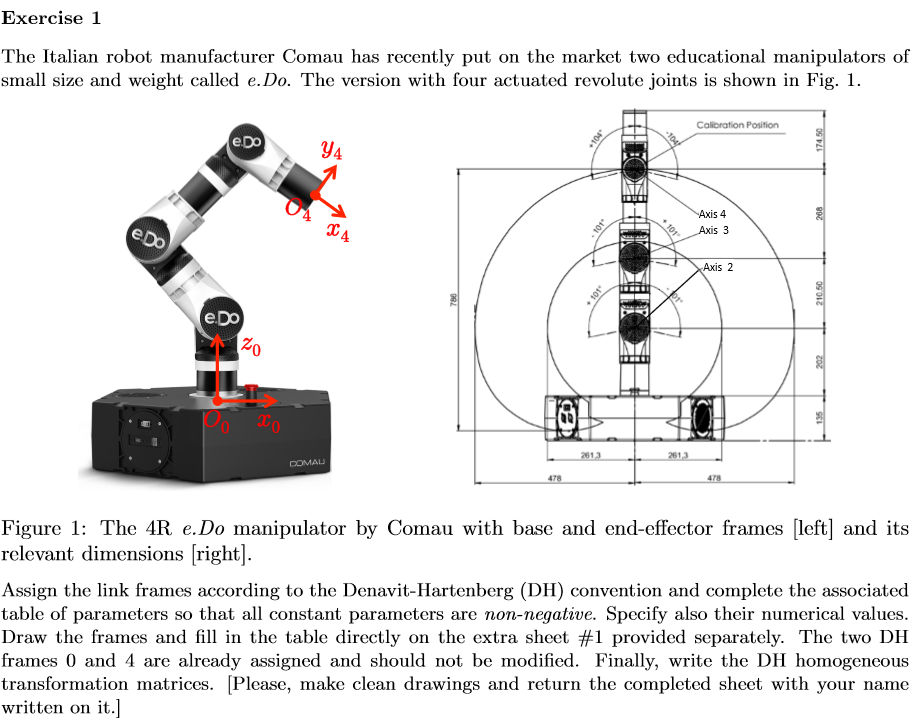

close all
clear all
clc

 NJoints=4

NJoints = 4

% 
 q = sym('q',[1 NJoints],'real')

$$q = \left(\begin{array}{cccc} q_{1} & q_{2} & q_{3} & q_{4} \end{array}\right)$$

 q_d1 = sym('q_d1',[1 NJoints],'real')

$$q\_d1 = \left(\begin{array}{cccc} q_{\mathrm{d11}} & q_{\mathrm{d12}} & q_{\mathrm{d13}} & q_{\mathrm{d14}} \end{array}\right)$$


 d = sym('d',[1 NJoints],'real')

$$d = \left(\begin{array}{cccc} d_{1} & d_{2} & d_{3} & d_{4} \end{array}\right)$$

 alpha = sym('alpha',[1 NJoints],'real')

$$alpha = \left(\begin{array}{cccc} \alpha_{1} & \alpha_{2} & \alpha_{3} & \alpha_{4} \end{array}\right)$$

 a = sym('a',[1 NJoints],'real')

$$a = \left(\begin{array}{cccc} a_{1} & a_{2} & a_{3} & a_{4} \end{array}\right)$$

 dh = [pi/2 0 202 q(1);
         0   210.5 0  q(2);
         0   268  0  q(3);
         0   174.5 0  q(4)]

$$dh = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & 202 & q_{1}\\ 0 & \frac{421}{2} & 0 & q_{2}\\ 0 & 268 & 0 & q_{3}\\ 0 & \frac{349}{2} & 0 & q_{4} \end{array}\right)$$

 dht = getDHforTB(dh,'alpha')

n = 4

dht =          0  202.0000         0    1.5708
         0         0  210.5000         0
         0         0  268.0000         0
         0         0  174.5000         0


comau = SerialLink(dht)

 
comau = 
 
noname:: 4 axis, RRRR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        202|          0|     1.5708|          0|
|  2|         q2|          0|      210.5|          0|          0|
|  3|         q3|          0|        268|          0|          0|
|  4|         q4|          0|      174.5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


olddigits=digits(4)

olddigits = 32

for i_=1:NJoints
   vpa(comau.links(i_).A(q(i_)),2)
end

$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & -6.123e-17\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 6.123e-17\,\cos\left(q_{1}\right) & -1.0\,\cos\left(q_{1}\right) & 0\\ 0 & 1.0 & 6.123e-17 & 202.0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left(q_{2}\right) & -1.0\,\sin\left(q_{2}\right) & 0 & 210.5\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & 210.5\,\sin\left(q_{2}\right)\\ 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left(q_{3}\right) & -1.0\,\sin\left(q_{3}\right) & 0 & 268.0\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & 268.0\,\sin\left(q_{3}\right)\\ 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left(q_{4}\right) & -1.0\,\sin\left(q_{4}\right) & 0 & 174.5\,\cos\left(q_{4}\right)\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & 174.5\,\sin\left(q_{4}\right)\\ 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

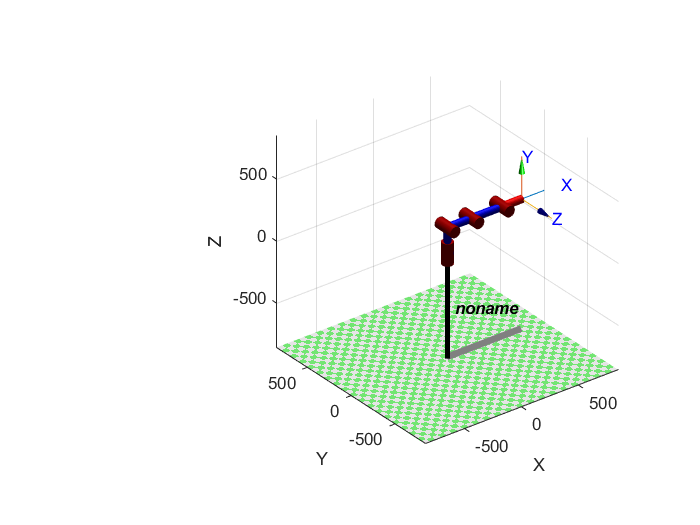

digits(olddigits)
comau.teach([0 0 0 0])

## exercise 3

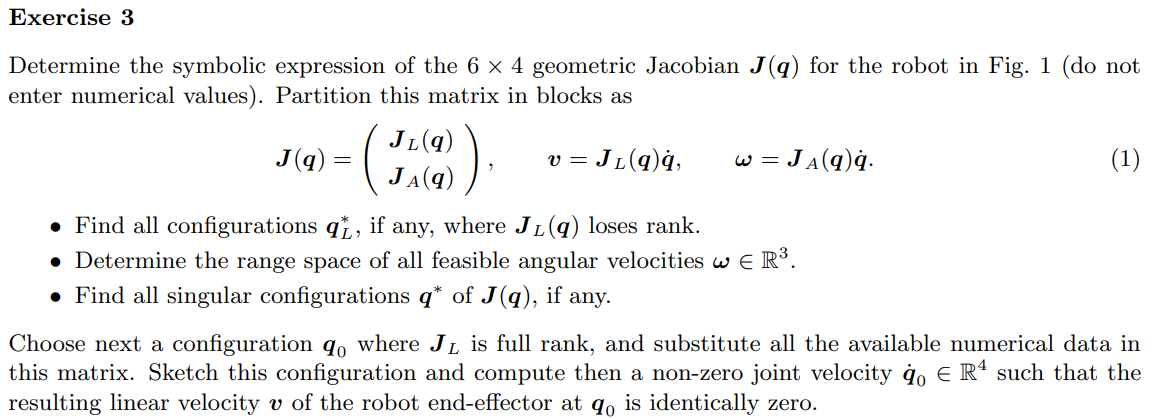

% sigma=['RRRR']
% q_=[0,0,pi/2,0]';
% dhsym_=subs(dh,q',q_)
% dhsym = [pi/2  0       d(1)    q(1);
%          0          a(2)    0       q(2);
%          0          a(3)    0       q(3);
%          0          a(4)    0       q(4)]
% [T_total T_Partial,RTotal,RPartial,PTotal, PPartial] = getTransformationMatrix(dhsym_,'alpha',true);
% PTotal
% [JL, JA,JLs, JAs] = getJacobian(dhsym_, sigma, 'alpha');
% JL1=RPartial{1}'*JL
% H=eye(NJoints,NJoints);
% H(3,2)=-1;
% H(4,3)=-1;
% JL1abs=simplify(JL1*H)
% rank(JL1abs)
% sincos =getShortNotation_SinCos(NJoints)
% toShortNotation(JL1abs,sincos)
% JA1=simplify(RPartial{1}'*JA)
% rank([JL;JA])
% rank([JL1abs;JA1])
% Jred=[JL1abs(1:2,:);JA1(2:end,:)]
% detJ=simplify(det(Jred))
% 
% v=[0,0,0]' ;
% qb_d1_=solve(v==JL*q_d1' )
% [qdvarray_,qdvnames_,vartosolve] =solvetoarray(qb_d1_,q' )
% vpa(qdvarray_)
% % pause()






## Exercise 4

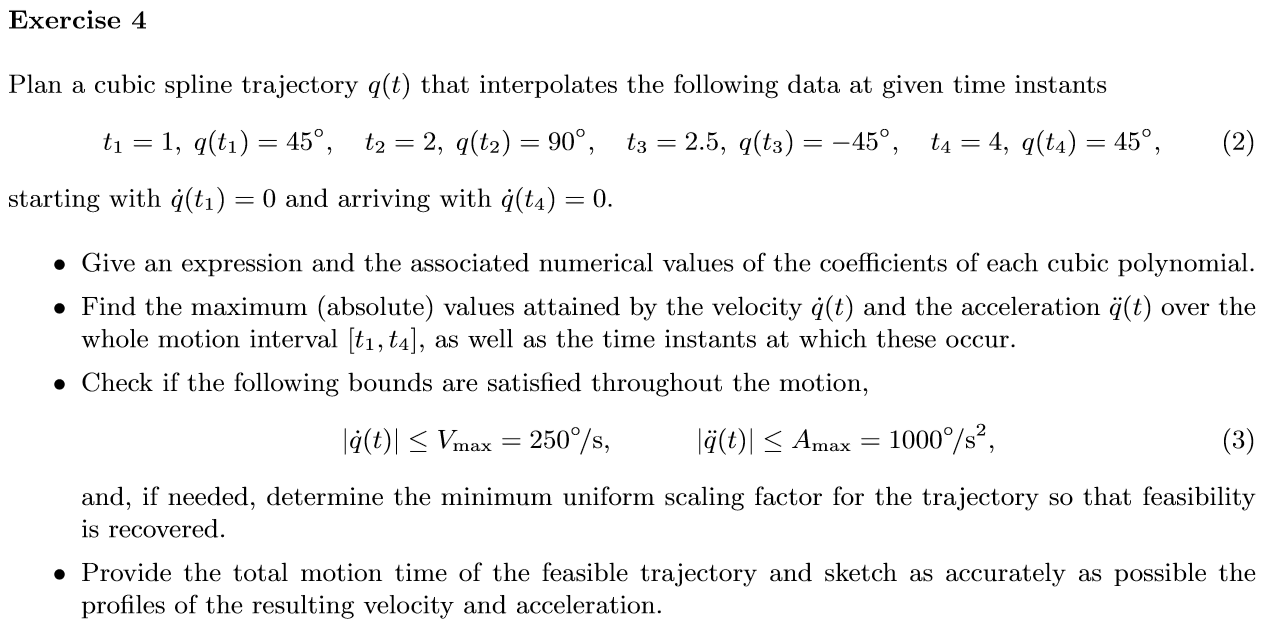

The pieces of the function must be continuous in velocity, and start and finish in zero speed (Rest-to-Rest). Those are the conditions listed below.

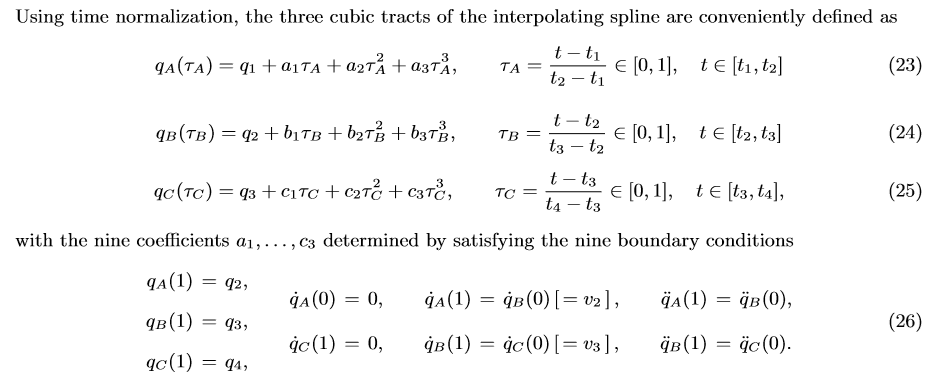

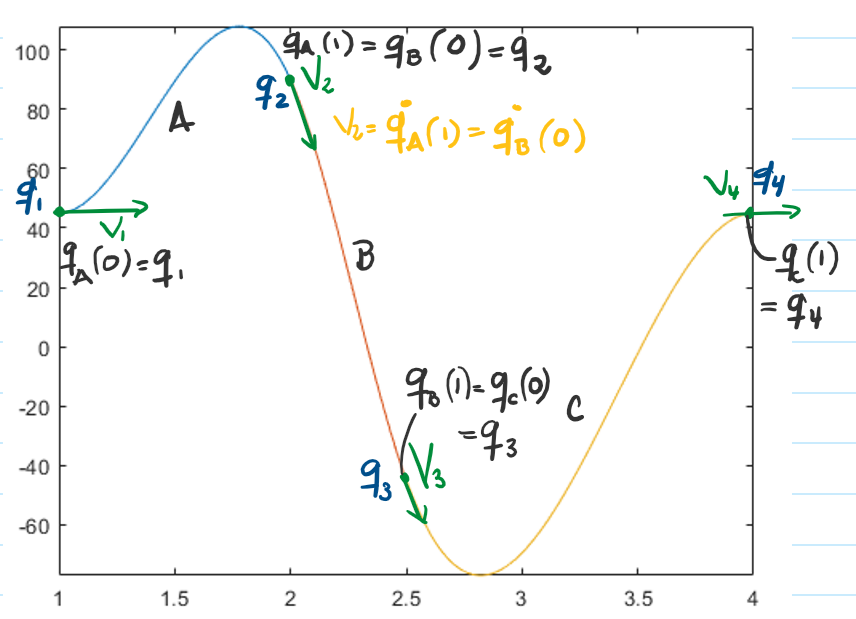

% q = sym('q',[1,4]);
% syms t t1 t2 v2 v3 t3 t4

### Part A

% a = sym('a',[1 3]);
% tao = (t-t1)/(t2-t1)
% qa = q(1) + a(1)*tao + a(2)*tao^2 + a(3)*tao^3 %tao must be defined as a function of t
% wa = diff(qa,t)
% % Forming the equation system for part A
% 
% eqA(1) = subs(qa,t,t2) == q(2);
% eqA(2) = simplify(subs(wa,t,t1)) == 0; % t = t1 is tao = 0
% eqA(3) = simplify(subs(wa,t,t2)) == v2; % t = t2 is tao = 1
% eqA.'
% [a1 a2 a3] = solve(eqA.',a)

### Part B

% taob = (t-t2)/(t3-t2)
% b = sym('b',[1 3]);
% 
% qb = q(2) + b(1)*taob + b(2)*taob^2 + b(3)*taob^3 %tao must be defined as a function of t
% wb = diff(qb,t)
%  
% % Forming the equation system for part B
% 
% eqB(1) = subs(qb,t,t3) == q(3);
% eqB(2) = simplify(subs(wb,t,t2)) == v2; % t = t1 is tao = 0
% eqB(3) = simplify(subs(wb,t,t3)) == v3; % t = t2 is tao = 1
% eqB.'
% [b1 b2 b3] = solve(eqB.',b) 
% 

### Part C

% taoc = (t-t3)/(t4-t3)
% c = sym('c',[1 3]);
% 
% qc = q(3) + c(1)*taoc + c(2)*taoc^2 + c(3)*taoc^3 %tao must be defined as a function of t
% wc = diff(qc,t)
%  
% % Forming the equation system for part C
% 
% eqC(1) = subs(qc,t,t4) == q(4);
% eqC(2) = simplify(subs(wc,t,t3)) == v3; % t = t1 is tao = 0
% eqC(3) = simplify(subs(wc,t,t4)) == 0; % t = t2 is tao = 1
% eqC.'
% [c1, c2, c3] = solve(eqC.',c)

% %Look for the velocity values
% acca= diff(wa,t)
% accb= diff(wb,t)
% accc= diff(wc,t)
% 
% acca_1 =simplify(subs(acca,[t a(2) a(3)],[t2 a2 a3]))
% accb_0 =simplify(subs(accb,[t b(2) b(3)],[t2 b2 b3]))
% accb_1 =simplify(subs(accb,[t b(2) b(3)],[t3 b2 b3]))
% accc_0 =simplify(subs(accc,[t c(2) c(3)],[t3 c2 c3]))
% 
% [v2sol, v3sol] = solve([acca_1 == accb_0;
%                        accb_1 == accc_0],[v2 v3])

% vars = [t1 t2 t3 t4 q];
% values = [1 2 2.5 4 45 90 -45 45];

% v2s = eval(subs(v2sol,vars,values))
% v3s = eval(subs(v3sol,vars,values))
% 
% % Da lo mismo que en el ejercicio!! :D lol casi nunca da xD
% 
% vars = [vars v2 v3]
% values = [values v2s v3s]

% aa = [a1 a2 a3]
% aa = eval(subs(aa, vars, values))
% 
% bb = [b1 b2 b3]
% bb = eval(subs(bb, vars, values))
% 
% cc = [c1 c2 c3]
% cc = eval(subs(cc, vars, values))
% vars = [vars a b c];
% values = [values aa bb cc]

% spa = subs(qa,vars,values)
% spb = subs(qb,vars,values)
% spc = subs(qc,vars,values)

% %Graphic the spline curve
% figure
% fplot(spa,[1,2])
% hold on
% fplot(spb,[2 2.5])
% fplot(spc,[2.5 4])
% 
% figure
% fplot(diff(spa,t),[1,2])
% hold on
% fplot(diff(spb,t),[2 2.5])
% fplot(diff(spc,t),[2.5 4])
% 
% figure
% fplot(diff(diff(spa,t),t),[1,2])
% hold on
% fplot(diff(diff(spb,t),t),[2 2.5])
% fplot(diff(diff(spc,t),t),[2.5 4])

## Exercise 4 - Second approach

clear;
% Define all variables.
% Number of cubic splines
N = 4 % No. of points
M = N-1 % No. of splines = # points - 1

q = sym('q', [N,1]);
t = sym('t', [N,1]);
% We'll denote [qA, qB, qC] (material notation) = [Q1, Q2, Q3] (Matlab friendly notation)
% In uppercase to not confuse with the actual points. Althought many of
% them are equivalent

Q = sym('Q', [M,1]); % Angle value
Qd = sym('Qd', [M,1]); % Angular velocity
Qdd = sym('Qdd', [M,1]); % Angular acceleration
v = sym('v', [M,1]); % Speed in splines unions

%ak = sym('ak', [M,1]); 
syms t_ % Time variable. Underscore to avoid confusion with symvector t

eq_k = sym(zeros(M,3)) % Create a variable to store the equations, but not necessary. Just for debugging.

% Coefficients matrix. In the solution would be a, b and c coefficients. 
% a(1) = ak(1).ak_1  ; c(2) = ak(3).ak_2
ak_ = sym('ak_',[3 1]); % 3 because it's the number of coefficients of a cubic spline.

for i = 1:M
    tau = (t_-t(i))/(t(i+1)-t(i))
    Q(i) = q(i) + ak_(1)*tau + ak_(2)*tau^2 + ak_(3)*tau^3 % Spline equation
    Qd(i) = diff(Q(i),t_) % Get angular speed.
    
    
    % Rest-to-rest conditions
    if i == 1 
        v_init = 0
    else
        v_init = v(i)
    end
    
    if i == M
        v_end = 0
    else
        v_end = v(i+1)
    end
    
    % For sytstem of equations
    eq_k(i,1) = subs(Q(i),t_,t(i+1)) == q(i+1) % At the end of the interval, the position is the next q.
    eq_k(i,2) = simplify(subs(Qd(i),t_,t(i))) == v_init % Beggining of interval, tau = 0, match last velocity
    eq_k(i,3) = simplify(subs(Qd(i),t_,t(i+1))) == v_end % End of interval, tau = 1, match next velocity
    
    ak(i) = solve(eq_k(i,:).',ak_)
end
printStruct(ak)

for i = 1:M
    Qdd(i) = diff(Qd(i),t_) % left to display the intermediate step.
    Qdd(i) = simplify(subs(Qdd(i),ak(i)))
    if i > 1
        Qdd_end1 = subs(Qdd(i-1),t_,t(i)) % End of first segment
        Qdd_init2 = subs(Qdd(i),t_,t(i)) % Beggining of sencond segment
        v_eq(i) = simplify(Qdd_end1 == Qdd_init2)
        %v_sol(i) = simplify(solve(Qdd_end1 == Qdd_init2, v(i))) 
    end
end
v_sol_sym = solve(v_eq, v) % solve for speed at the joint of segments
printStruct(v_sol_sym) 

Replace values to get the numerical answer

t_values = [1,2,2.5,4];%[1,2.2324,2.8487,4.6973];%
q_values = [45,90,-45,45];
vars = [t,q]

values = [t_values; q_values].' 
names = fieldnames(v_sol_sym)
v_sol = zeros(1,M);
for i = 1:length(names)
    v_sol(i) = eval(subs(getfield(v_sol_sym,names{i}),vars,values))
end
% The answers coincide with the professor's solution

### Get splines functions 

% Get splines functions
spline_M=[];
Aw_M=[];
Aa_M=[];
Ajerk_M=[];
for i = 1:M
    Q_ = subs(Q(i),ak(i)) % substitute found values
    Q_ = subs(Q_,v,v_sol.')
    spline_fun(i) = subs(Q_, vars, values)
    %%modified by DAvid
    Aw_fun(i)=diff(spline_fun(i),t_);
    Aa_fun(i)=diff(Aw_fun(i),t_);
    Ajerk_fun=diff(Aa_fun(i),t_);
    
    %searching maximus and minumus
    spline_M_=vpasolve(spline_fun(i)==0,[t_values(i),t_values(i+1)]);
    Aw_M_=vpasolve(Aw_fun(i)==0,[t_values(i),t_values(i+1)]);
    Aa_M_=vpasolve(Aa_fun(i)==0,[t_values(i),t_values(i+1)]);
%     Ajerk_M_=vpasolve(Ajerk_fun(i)==0,[t_values(i),t_values(i+1)]);

    
    %% assigning
    if(isempty(spline_M_)==0)
        spline_M=[spline_M;spline_M_];
    end
    if(isempty(Aw_M_)==0)
        Aw_M=[Aw_M;Aw_M_];
    end
    if(isempty(Aa_M_)==0)
        Aa_M=[Aa_M;Aa_M_];
    end
%         if(isempty(Ajerk_M_)==0)
%         Ajerk_M=[Ajerk_M;Ajerk_M_];
%     end
end

### Get splines plots

% Angles
figure
for i = 1:M
    fplot(spline_fun(i),t_values(i:i+1)) 
    hold on
end

% Angular velocity
figure
for i = 1:M
%     fplot(diff(spline_fun(i),t_),t_values(i:i+1))
    fplot(Aw_fun(i),t_values(i:i+1))

    hold on
end

% Angular acceleration
figure
for i = 1:M
%     fplot(diff(diff(spline_fun(i),t_)),t_values(i:i+1))
    fplot(Aa_fun(i),t_values(i:i+1))
    hold on
end


## finding maxs velocities

vmax=250
Aw_peak=diag(subs(Aw_fun,t_,[Aa_M]))
[Kscalmax,indk]=max(abs(Aw_peak/vmax))
t_values_scaled=t_values(1)+(t_values-t_values(1))*Kscalmax;
% t_values_=t_values(1)+Scaledtime
% kscal_ind=find(>1)


